Do signal generation

% Test parameters
M = 5; % Number of antennas
N = 20; % Number of samples
theta = [-20 ; 30 ]; % Directions of arrival in radians
f = [0.1; 0.3]; % Normalized frequencies
SNR = [20; 20]; % Signal-to-noise ratios in dB

% Generate data and perform SVD for original data
[X, ~, ~] = gen_data(M, N, 0.5, theta, f, SNR);
[~, Singular] = svd(X);
rank(X)

ans = 5

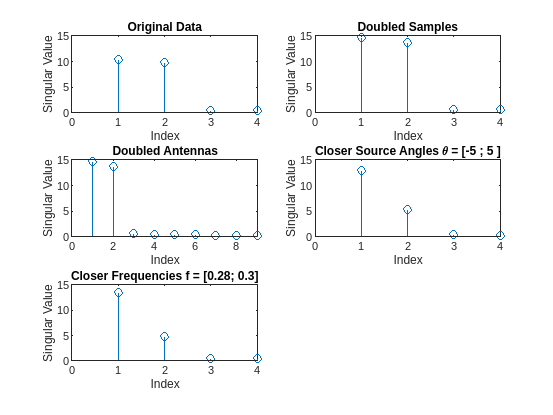


% Double samples
N = 40;
[X_sample, ~, ~] = gen_data(M, N, 0.5, theta, f, SNR);
[~, Singular_sample] = svd(X_sample);

% Double antennas
M = 10; N = 20;
[X_ant, ~, ~] = gen_data(M, N, 0.5, theta, f, SNR);
[~, Singular_ant] = svd(X_ant);

% Make source angles closer
M = 5; theta = [-5 ; 5 ];
[X_angle, ~, ~] = gen_data(M, N, 0.5, theta, f, SNR);
[~, Singular_angle] = svd(X_angle);

% Make frequencies closer
theta = [-20 ; 30 ]; f = [0.28; 0.3];
[X_freq, ~, ~] = gen_data(M, N, 0.5, theta, f, SNR);
[~, Singular_freq] = svd(X_freq);

% Store singular values and titles in arrays
singular_values = {diag(Singular), diag(Singular_sample), diag(Singular_ant), diag(Singular_angle), diag(Singular_freq)};
titles = ["Original Data", "Doubled Samples", "Doubled Antennas", "Closer Source Angles \theta = [-5 ; 5 ]", "Closer Frequencies f = [0.28; 0.3]"];

% Create a figure and plot all the singular values in subplots
figure;
num_plots = length(singular_values);
for i = 1:num_plots
    subplot(ceil(num_plots/2), 2, i); % Arrange subplots in a grid
    stem(singular_values{i});
    title(titles(i));
    xlabel('Index');
    ylabel('Singular Value');
    xlim([0, length(singular_values{i})-1]);
    ylim([0, 15]);
end

Estimate DOA

clear all;

%implementation of esprit
M = 5; % Number of antennas
N = 20; % Number of samples
theta = [-20 ; 30]; % Directions of arrival in radians
f = [0.1; 0.3]; % Normalized frequencies
SNR = 20*ones([1,2]); % Signal-to-noise ratios in dB
delta=0.5;
% Generate data and perform SVD for original data
[X, ~, ~] = gen_data(M, N, delta, theta, f, SNR);

theta=esprit(X,2,delta)

theta =   -19.9083
   29.8636


Estimating Frequencies

clear all;
% Parameters
M = 5; % Number of antennas
N = 20; % Number of samples
theta = [-20 ; 30 ]; % Directions of arrival in radians
f = [0.2; 0.3]; % Normalized frequencies
SNR = 20*ones([1,2]); % Signal-to-noise ratios in dB
delta = 0.5;

% Generate data
[X, ~, ~] = gen_data(M, N, delta, theta, f, SNR);

% Perform ESPRIT
% freq = abs(espritfreq(X, 2));
freq=espritfreq2(X,2);

% Display results
disp('Estimated Frequencies:');

Estimated Frequencies:


disp(freq);

    0.2999
    0.1994



Jointly estimating DOA and Frequency

clear all;
% Parameters
M = 4; % Number of antennas
N = 20; % Number of samples
theta = [-20 ; 30]; % Directions of arrival in radians
f = [0.1; 0.2]; % Normalized frequencies
SNR = 20*ones([1,2]); % Signal-to-noise ratios in dB
delta = 0.5;
d=2;

% Generate data
[X, ~, ~] = gen_data(M, N, delta, theta, f, SNR);



[theta_joint,f_joint]=joint(X,d,3)

ans = 5

ans = 7

ans = 6

ans = 8

ans = 9

ans = 11

ans = 10

ans = 12

theta_joint =   -20.0230
   29.9300


f_joint =     0.1990
    0.1000


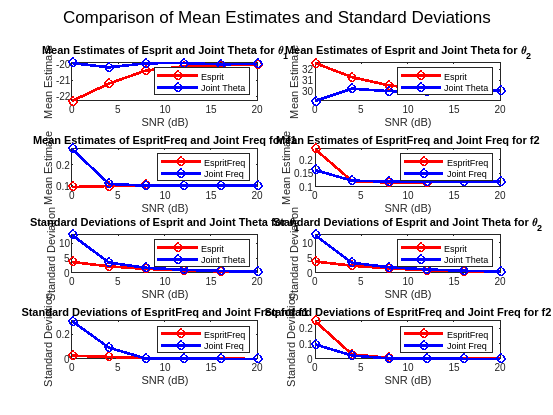



% Parameters
SNR_values = 0:4:20;
d = 2;
M = 3;
N = 20;
theta = [-20, 30];
f = [0.1, 0.12];
tot_iter = 1000;
delta=0.5;
% Initialize results arrays
values_esprit = zeros(tot_iter,length(SNR_values), d);
values_espritfreq = zeros(tot_iter,length(SNR_values), d);
values_joint_freq = zeros(tot_iter,length(SNR_values), d);
values_joint_theta = zeros(tot_iter,length(SNR_values), d);



% Perform iterations
for i = 1:tot_iter
    for snr_idx = 1:length(SNR_values)
        snr = SNR_values(snr_idx);
        SNR=ones(1,d)*snr;
        % Generate data
        [X, A, S] = gen_data(M, N, delta, theta, f, SNR);
        theta_esprit = esprit(X, d,delta);
        values_esprit(i,snr_idx, :) = theta_esprit;
        freqs_espritfreq = espritfreq(X, d);
        values_espritfreq(i,snr_idx, :) = freqs_espritfreq;

        [theta_joint, f_joint] = joint(X, d, 6);
        values_joint_theta(i,snr_idx, :) = theta_joint;
        values_joint_freq(i,snr_idx, :) = f_joint;

    end
end

% Calculate means and standard deviations
mean_esprit = mean(values_esprit, 1);
std_esprit = std(values_esprit, 1);
mean_espritfreq = mean(values_espritfreq, 1);
std_espritfreq = std(values_espritfreq, 1);
mean_joint_theta = mean(values_joint_theta, 1);
std_joint_theta = std(values_joint_theta, 1);
mean_joint_freq = mean(values_joint_freq, 1);
std_joint_freq = std(values_joint_freq, 1);

% Calculate means and standard deviations
mean_esprit = mean(values_esprit, 1);
std_esprit = std(values_esprit, 1);
mean_espritfreq = mean(values_espritfreq, 1);
std_espritfreq = std(values_espritfreq, 1);
mean_joint_theta = mean(values_joint_theta, 1);
std_joint_theta = std(values_joint_theta, 1);
mean_joint_freq = mean(values_joint_freq, 1);
std_joint_freq = std(values_joint_freq, 1);

% Plotting all figures in a 4x2 grid
figure;

% Plot mean estimates of Esprit and Joint Theta for theta 1
subplot(4, 2, 1);
plot(SNR_values, mean_esprit(:, :, 1), 'r-o', 'LineWidth', 2);
hold on;
plot(SNR_values, mean_joint_theta(:, :, 1), 'b-o', 'LineWidth', 2);
hold off;
xlabel('SNR (dB)');
ylabel('Mean Estimate');
title('Mean Estimates of Esprit and Joint Theta for \theta_1');
legend('Esprit', 'Joint Theta');

% Plot mean estimates of Esprit and Joint Theta for theta 2
subplot(4, 2, 2);
plot(SNR_values, mean_esprit(:, :, 2), 'r-o', 'LineWidth', 2);
hold on;
plot(SNR_values, mean_joint_theta(:, :, 2), 'b-o', 'LineWidth', 2);
hold off;
xlabel('SNR (dB)');
ylabel('Mean Estimate');
title('Mean Estimates of Esprit and Joint Theta for \theta_2');
legend('Esprit', 'Joint Theta');

% Plot mean estimates of EspritFreq and Joint Freq for f1
subplot(4, 2, 3);
plot(SNR_values, mean_espritfreq(:, :, 1), 'r-o', 'LineWidth', 2);
hold on;
plot(SNR_values, mean_joint_freq(:, :, 2), 'b-o', 'LineWidth', 2);
hold off;
xlabel('SNR (dB)');
ylabel('Mean Estimate');
title('Mean Estimates of EspritFreq and Joint Freq for f1');
legend('EspritFreq', 'Joint Freq');

% Plot mean estimates of EspritFreq and Joint Freq for f2
subplot(4, 2, 4);
plot(SNR_values, mean_espritfreq(:, :, 2), 'r-o', 'LineWidth', 2);
hold on;
plot(SNR_values, mean_joint_freq(:, :, 1), 'b-o', 'LineWidth', 2);
hold off;
xlabel('SNR (dB)');
ylabel('Mean Estimate');
title('Mean Estimates of EspritFreq and Joint Freq for f2');
legend('EspritFreq', 'Joint Freq');

% Plot standard deviations of Esprit and Joint Theta for theta 1
subplot(4, 2, 5);
plot(SNR_values, std_esprit(:, :, 1), 'r-o', 'LineWidth', 2);
hold on;
plot(SNR_values, std_joint_theta(:, :, 1), 'b-o', 'LineWidth', 2);
hold off;
xlabel('SNR (dB)');
ylabel('Standard Deviation');
title('Standard Deviations of Esprit and Joint Theta for \theta_1');
legend('Esprit', 'Joint Theta');

% Plot standard deviations of Esprit and Joint Theta for theta 2
subplot(4, 2, 6);
plot(SNR_values, std_esprit(:, :, 2), 'r-o', 'LineWidth', 2);
hold on;
plot(SNR_values, std_joint_theta(:, :, 2), 'b-o', 'LineWidth', 2);
hold off;
xlabel('SNR (dB)');
ylabel('Standard Deviation');
title('Standard Deviations of Esprit and Joint Theta for \theta_2');
legend('Esprit', 'Joint Theta');

% Plot standard deviations of EspritFreq and Joint Freq for f1
subplot(4, 2, 7);
plot(SNR_values, std_espritfreq(:, :, 1), 'r-o', 'LineWidth', 2);
hold on;
plot(SNR_values, std_joint_freq(:, :, 2), 'b-o', 'LineWidth', 2);
hold off;
xlabel('SNR (dB)');
ylabel('Standard Deviation');
title('Standard Deviations of EspritFreq and Joint Freq for f1');
legend('EspritFreq', 'Joint Freq');

% Plot standard deviations of EspritFreq and Joint Freq for f2
subplot(4, 2, 8);
plot(SNR_values, std_espritfreq(:, :, 2), 'r-o', 'LineWidth', 2);
hold on;
plot(SNR_values, std_joint_freq(:, :, 1), 'b-o', 'LineWidth', 2);
hold off;
xlabel('SNR (dB)');
ylabel('Standard Deviation');
title('Standard Deviations of EspritFreq and Joint Freq for f2');
legend('EspritFreq', 'Joint Freq');


% Adjust layout
sgtitle('Comparison of Mean Estimates and Standard Deviations');

Zero forcing beamformers

clear all;
% Test parameters
M = 5; % Number of antennas
N = 20; % Number of samples
theta = [-20 ; 30 ]; % Directions of arrival in radians
f = [0.1; 0.3]; % Normalized frequencies
SNR = 0*ones([1,2]); % Signal-to-noise ratios in dB
d=2;
delta=0.5;

% Generate data and perform SVD for original data
[X, ~, S] = gen_data(M, N, 0.5, theta, f, SNR);

%ZF DOA
theta_est=esprit(X,2,delta);
A = zeros(M, d);
for i = 1:d
        for m = 1:M
            % Calculate array response
            A(m, i) = exp((m-1)*1i * 2 * pi * delta * sind(theta_est(i)));
        end
end
W_1=pinv(A);
S_est1=W_1*X;

f_est=espritfreq(X, d);
S_est2= zeros(length(theta), N);
for i = 1:d
        for n = 1:N
            % Generate signal
            S_est2(i, n) = exp(1i * 2 * pi * f_est(i) * n);
        end
    
end

W_2=pinv(X*pinv(S_est2));


Spatial response

spatial_response11=zeros(1,181);
spatial_response12=zeros(1,181);
A = zeros(M, d);

for m = 1:M
        A(m, :) = exp((m-1)*1i * 2 * pi * delta * sind(i));
end

for i=-90:90
    % spatial_response1(i+91)=abs(sum(W_1'*A,"all"));
    spatial_response11(i+91)=norm(W_1(1,:)*A(:,1));
    spatial_response12(i+91)=norm(W_1(2,:)*A(:,2));
end

spatial_response21=zeros(1,181);
spatial_response22=zeros(1,181);
for i=-90:90
    % spatial_response2(i+91)=abs(sum(W_2'*A2,"all"));
    spatial_response21(i+91)=norm(W_2(1,:)*A(:,1));
    spatial_response22(i+91)=norm(W_2(2,:)*A(:,2));
end



figure;
plot(-90:90, spatial_response11);

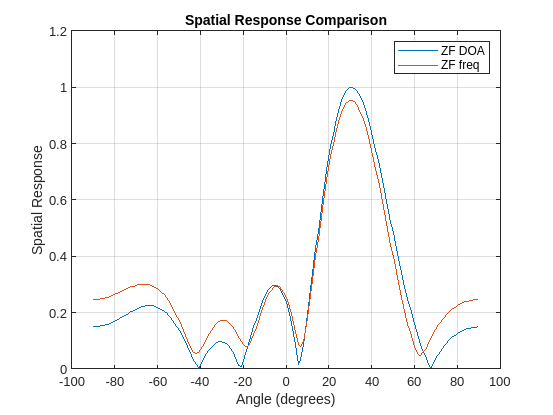

hold on;
plot(-90:90, spatial_response21);
xlabel('Angle (degrees)');
ylabel('Spatial Response');
title('Spatial Response Comparison');
legend('ZF DOA', 'ZF freq');
grid on;

figure;
plot(-90:90, spatial_response12);
hold on;
plot(-90:90, spatial_response22);
xlabel('Angle (degrees)');
ylabel('Spatial Response');
title('Spatial Response Comparison');
legend('ZF DOA', 'ZF freq');
grid on;

Functions

function [X,A,S] = gen_data(M,N,delta,theta,f,SNR)
    % Initialize matrices
    num_sources=length(theta);
    X = zeros(M, N);
    A = zeros(M, num_sources);
    S = zeros(length(theta), N);
    Noise=zeros(M,N);
    
    % Generate the signals and array responses
    for d = 1:num_sources
        %calculate signal amplitude
        SNR_linear = 10.^(SNR(d) / 10);
        amplitude =sqrt(SNR_linear);
        for n = 1:N
            % Generate signal
            S(d, n) = exp(1i * 2 * pi * f(d) * n);
        end
        for m = 1:M
            % Calculate array response
            A(m, d) = exp((m-1)*1i * 2 * pi * delta * sind(theta(d)));
        end
    end

    % Generate noise with consistent dimensions
    real_noise = randn(size(X));
    imag_noise = randn(size(X));
    % Combine real and imaginary parts to form complex noise
    Noise = real_noise + 1i * imag_noise;
    signal_power = mean(abs(S(:).^2));

    % Scale noise to achieve desired SNR for each source
    for d = 1:num_sources
        SNR_linear = 10^(SNR(d) / 10);
        noise_power = signal_power / SNR_linear;
        Noise = Noise * sqrt(noise_power / mean(abs(Noise(:)).^2));
    end
    %caculate the M by N matrix X
    X=A*S;
    X = X + Noise;
end




function theta = esprit(X,d,delta)
    M=size(X,1);

    %let us group first M-1 and last M-1 data records
    X_1=X(1:M-1,:);
    Y=X(2:M,:);

    Z=[X_1;Y];
    [U_z,~,~]=svd(Z);
    U_z_hat=U_z(:,1:d);
    U_x_hat=U_z_hat(1:M-1,:);
    U_y_hat=U_z_hat(M:end,:);

    temp=pinv(U_x_hat)*U_y_hat;
    [T,Theta]=eig(temp);
    theta=sort(asind(angle(diag(Theta))/(2*pi*delta)));
end

function freqs = espritfreq(X, d)

    % Singular value decomposition
    [~, ~, V] = svd(X);
    V1 = V(1:end-1, 1:d);
    V2 = V(2:end, 1:d);
    D = eig(pinv(V1) * V2);
    
    freqs=real(log(D)/(2*pi*j));
    for i=1:d
        if freqs(i)>0
            freqs(i)=freqs(i)-1;
        end
    end
    freqs=sort(abs(freqs));   
  
end

function freq = espritfreq2(X,d)
    
    X=X.';
    N=size(X,1);
    %let us group first M-1 and last M-1 data records
    X_1=X(1:N-1,:);
    Y=X(2:N,:);

    Z=[X_1;Y];
    [U_z,~,~]=svd(Z);
    U_z_hat=U_z(:,1:d);
    U_x_hat=U_z_hat(1:N-1,:);
    U_y_hat=U_z_hat(N:end,:);

    temp=pinv(U_x_hat)*U_y_hat;
    [T,Theta]=eig(temp);
    freq=real(log(diag(Theta))/(2*pi*j));
end


function [theta,f] = joint(X,d,m)
    %lets create a m-smoothed X_m matrix
    N=size(X,2);
    M=size(X,1);
    Xm=zeros([m*M,N-m+1]);
    for i=1:m
        Xm((i-1)*M+1:i*M,: )=X(:,i:N-m+i);
    end

    %now lets take the SVD of Xm
    [Um,~,~]=svd(Xm);
    Um=Um(:,1:d);

    Um_phix=Um(1:M*(m-1),:);
    Um_phiy=Um(M+1:M*m,:);
    My=pinv(Um_phix)*Um_phiy;

    Um_theta_x=[];
    Um_theta_y=[];

    for i=1:m-1
        Um_theta_x=vertcat(Um_theta_x,Um(i*(M)+1:(i+1)*M-1,:));
        i*(M)+1
        (i+1)*M-1
        Um_theta_y=vertcat(Um_theta_y,Um(i*(M)+2:(i+1)*M,:));
        i*(M)+2
        (i+1)*M
    end
    Mz=pinv(Um_theta_x)*Um_theta_y;
    M=[My,Mz];
    [V,D]=joint_diag(M,1.0e-8);
    [~,v]=size(D);
    Phi=D(:,1:v/2);
    Theta=D(:,v/2+1:v);
    f=sort(angle(eig(Phi))/(2*pi),"desc");
    for i =1:d
        if f(i)<0
            f(i)=1+f(i);
        end
    end

    theta=sort( asind(angle(eig(Theta))/pi));

end


